# Linear Classifiers

We are going to develop a classification example, using the famous Iris dataset.

load fisheriris
f = figure;
gscatter(meas(:,1), meas(:,2), species,'rgb','o',5);
xlabel('Sepal length');
ylabel('Sepal width');

We can perform LDA, to obtain a linear classifier:

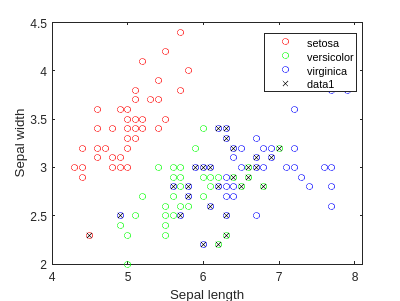

lda = fitcdiscr(meas(:,1:2),species);
ldaClass = resubPredict(lda);

figure(f)
bad = ~strcmp(ldaClass,species);
hold on;
plot(meas(bad,1), meas(bad,2), 'kx');
hold off;

Now we can draw the regions:

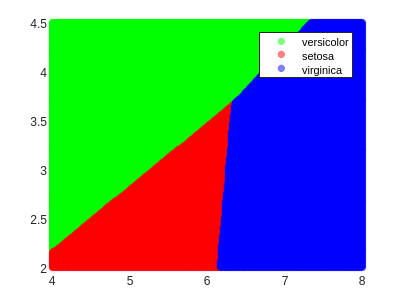

figure;
[x,y] = meshgrid(4:.01:8,2:.01:4.5);
x = x(:);
y = y(:);
j = predict(lda, [x y]);
colors = [0 1 0; 1 0 0; 0 0 1];
face_alpha = 0.5;

% Loop through unique species and plot points with custom colors and transparency
unique_species = unique(j);
for i = 1:length(unique_species)
    scatter(x(strcmp(j, unique_species{i})), y(strcmp(j, unique_species{i})), [], colors(i,:), 'o', 'filled', 'MarkerFaceAlpha', face_alpha);
    hold on;
end
legend('versicolor','setosa','virginica')

As we can see, the decision boundaries are hyperplanes (lines in the 2D case), which is a characteristic of linear classifiers.

Let's now repeat this with QDA, so that we can obtain non-linear regions:

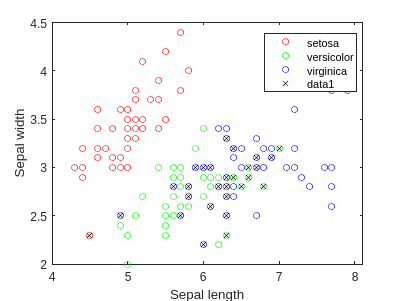

f2 = figure;
gscatter(meas(:,1), meas(:,2), species,'rgb','o',5);
xlabel('Sepal length');
ylabel('Sepal width');

qda = fitcdiscr(meas(:,1:2),species,'DiscrimType','quadratic');
qdaClass = resubPredict(qda);

figure(f2)
bad = ~strcmp(qdaClass,species);
hold on;
plot(meas(bad,1), meas(bad,2), 'kx');
hold off;

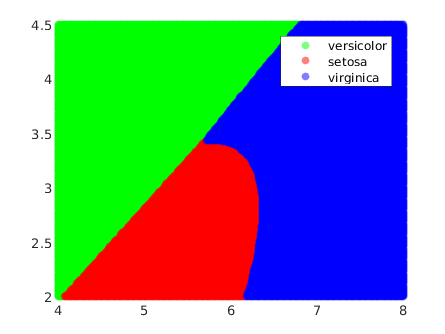


figure;
[x2,y2] = meshgrid(4:.01:8,2:.01:4.5);
x2 = x2(:);
y2 = y2(:);
j2 = predict(qda, [x2 y2]);
% Define custom colors for the species
colors = [0 1 0; 1 0 0; 0 0 1];
face_alpha = 0.5;

% Loop through unique species and plot points with custom colors and transparency
unique_species = unique(j2);
for i = 1:length(unique_species)
    scatter(x2(strcmp(j2, unique_species{i})), y2(strcmp(j2, unique_species{i})), [], colors(i,:), 'o', 'filled', 'MarkerFaceAlpha', face_alpha);
    hold on;
end
legend('versicolor','setosa','virginica')

In this example we observe that the decision boundaries are no longer linear: they are quadrics in the input space. This fact increases highly the shapes that these boundaries can take.

For instance, a hyperplane is always 'the same', in the sense that all hyperplanes are isomorphic. On the other hand, quadrics are much more complex. In 2D, for example, these are the conics, which can take the form of a line, a ellipse (with the circunference as special case), a parabola or an hyperbola. This variety increases highly with the dimensionality. In 3D and above they are usually called quadrics, and in 3D there are 17 standard-form types [[quadrics - wolfram mathworld]](https://mathworld.wolfram.com/QuadraticSurface.html#:~:text=Quadratic%20surfaces%20are%20also%20called,are%2017%20standard%2Dform%20types.).

A final example with a knn classifier:

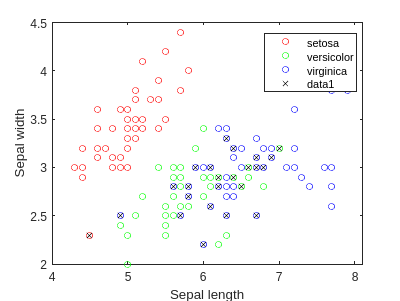

% Train kNN classifier
k = 5; % You can change this value to choose a different number of neighbors
knn = fitcknn(meas(:,1:2), species, 'NumNeighbors', k);
knnClass = resubPredict(knn);

% Plot the dataset and misclassified points
f3 = figure;
gscatter(meas(:,1), meas(:,2), species, 'rgb', 'o', 5);
xlabel('Sepal length');
ylabel('Sepal width');

bad_knn = ~strcmp(knnClass, species);
hold on;
plot(meas(bad_knn, 1), meas(bad_knn, 2), 'kx');
hold off;

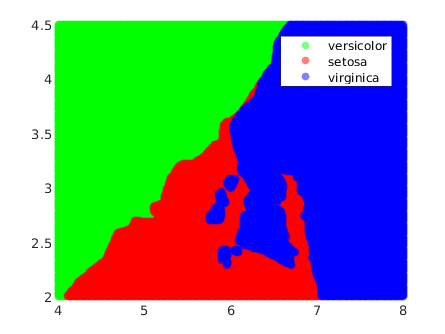


% Visualize the decision regions
figure;
[x3, y3] = meshgrid(4:.01:8, 2:.01:4.5);
x3 = x3(:);
y3 = y3(:);
j3 = predict(knn, [x3 y3]);

% Define custom colors for the species
colors = [0 1 0; 1 0 0; 0 0 1];
face_alpha = 0.5;

% Loop through unique species and plot points with custom colors and transparency
unique_species = unique(j3);
for i = 1:length(unique_species)
    scatter(x3(strcmp(j3, unique_species{i})), y3(strcmp(j3, unique_species{i})), [], colors(i,:), 'o', 'filled', 'MarkerFaceAlpha', face_alpha);
    hold on;
end
legend('versicolor','setosa','virginica')

This method generates more complex decision boundaries, which are not even continuous. This is because kNN is not optimizing an underlying function, which is ultimately what creates the continuous boundaries that we have seen in the previous methods. In this case, the boundaries are highly determined by the data instances.

It is a remarkable fact that they get smoother when k increases:

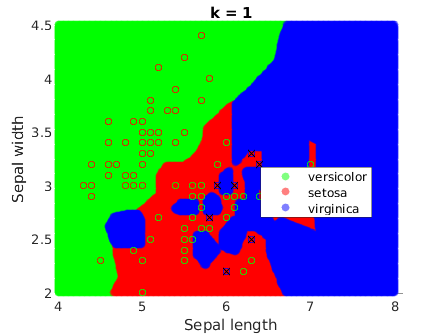

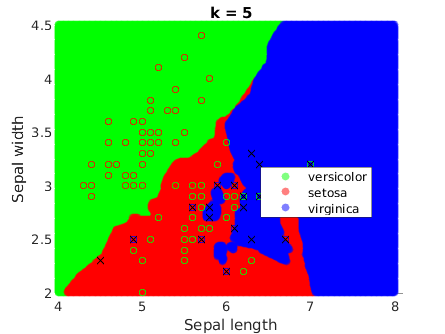

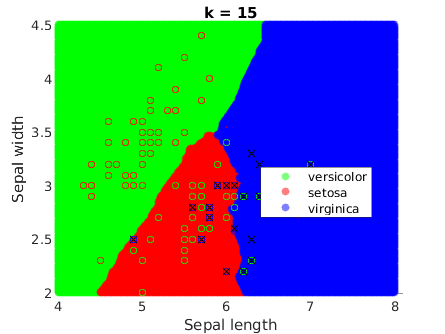

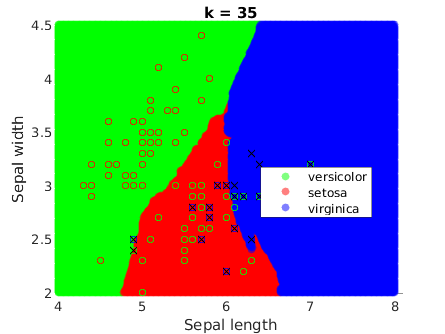

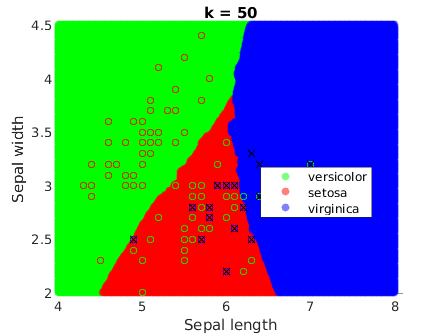

load fisheriris

% Define custom colors for the species
colors = [0 1 0; 1 0 0; 0 0 1];
face_alpha = 0.5;

k_values = [1, 5, 15, 35, 50];

for k_idx = 1:length(k_values)
    k = k_values(k_idx);

    % Train kNN classifier
    knn = fitcknn(meas(:,1:2), species, 'NumNeighbors', k);
    knnClass = resubPredict(knn);

    % Visualize the decision regions
    f = figure;
    [x, y] = meshgrid(4:.01:8, 2:.01:4.5);
    x = x(:);
    y = y(:);
    j = predict(knn, [x y]);

    % Loop through unique species and plot points with custom colors and transparency
    unique_species = unique(j);
    for i = 1:length(unique_species)
        scatter(x(strcmp(j, unique_species{i})), y(strcmp(j, unique_species{i})), [], colors(i,:), 'o', 'filled', 'MarkerFaceAlpha', face_alpha);
        hold on;
    end

    % Plot the original dataset on top of the decision regions
    gscatter(meas(:,1), meas(:,2), species, 'rgb', 'o', 5);

    % Plot misclassified points
    bad_knn = ~strcmp(knnClass, species);
    plot(meas(bad_knn, 1), meas(bad_knn, 2), 'kx');

    hold off;

    % Set title and labels
    title(sprintf('k = %d', k));
    xlabel('Sepal length');
    ylabel('Sepal width');
    legend('versicolor','setosa','virginica')
end